# CWT 2D Dispersion Relation Extraction

#### cc

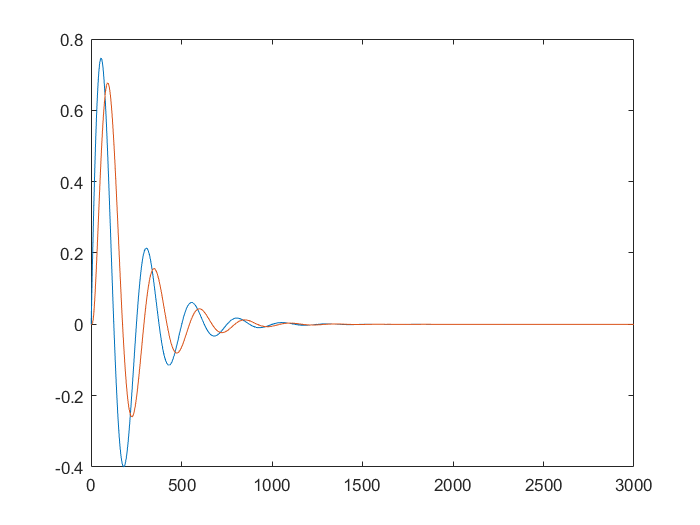

clear all; close all; clc;

% load('SimSignals.mat')
load('SimSignals87.mat')
figure
plot(S1)
hold on
plot(S2)
hold off

r = 2/1000;
fs =100000; %设定采样频率
dt = 1./fs;
FreqRange = [100 500 10];
VelocityRange = [0.2 10 0.2];
wavename = 'cmor3-3';
% wavename = 'amor';

%% CWT DPR
[E,freq,v,~,~, ~] = MeasurePVByTwoPTCWT(S1,S2,r,dt,FreqRange, VelocityRange, wavename);

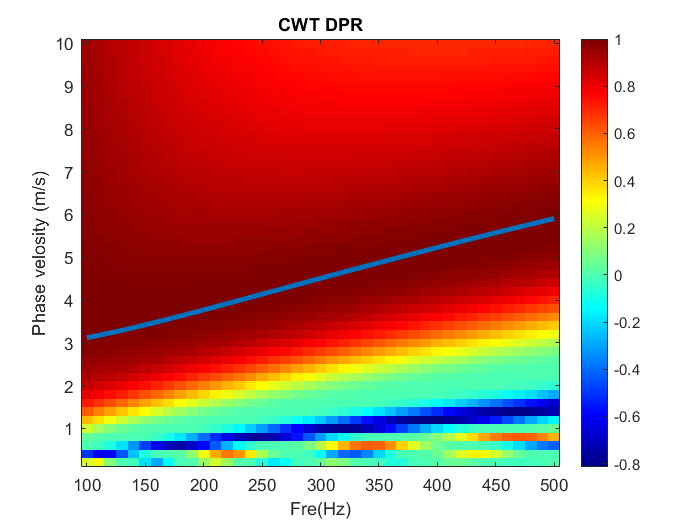

%% Plot
figure
imagesc([freq(1) freq(end)],[v(1) v(end)],E);
colormap(jet);
colorbar;
set(gca,'YDir','normal');
title('CWT DPR');
xlabel('Fre(Hz)');
ylabel('Phase velosity (m/s)');
hold on 
%E
for i=1:1:size(E,2)
    [~,I]=max(E(:,i));
    Vs_x(i) = v(I);
end

% Analytical solution
u1 = 8*10^3; % KPa
u2 = 7; % Pa*s
rho=1000;
omega = 2*pi*freq;
Vs= DPRFun(u1, u2,rho, freq);
plot(freq,Vs,'LineWidth', 3);

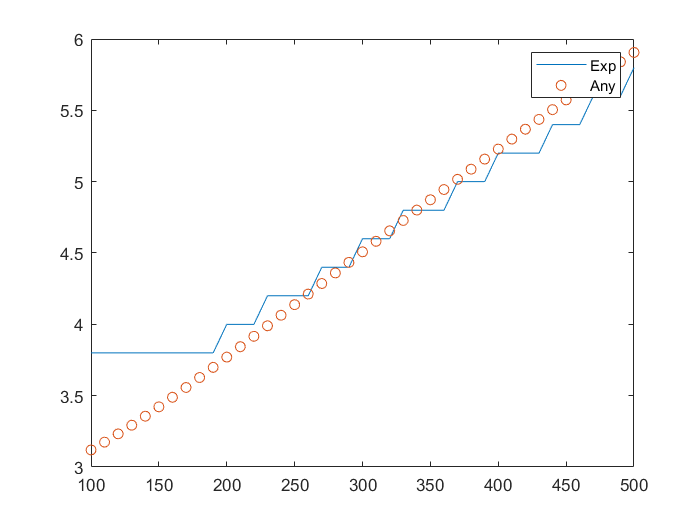

figure
plot(freq,Vs_x)
hold on
scatter(freq,Vs)
legend("Exp","Any")

# **Transfer k-f to t-f, in order to perfrom inverse CWT**

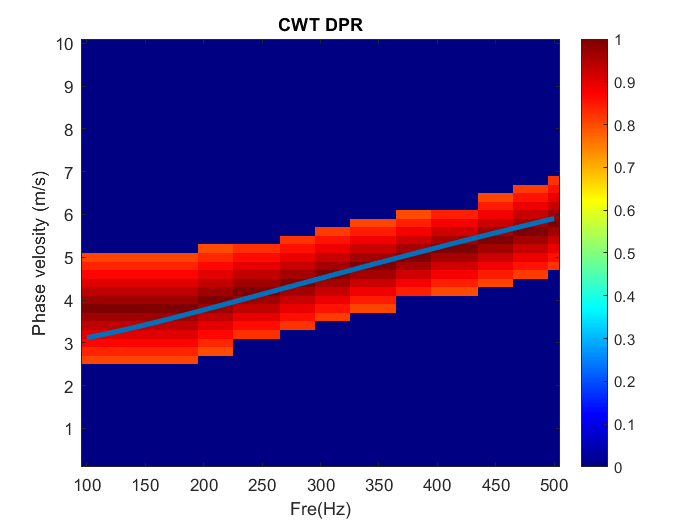

E_filter = zeros(length(freq),length(v));

for i=1:1:length(freq)
      for j=1:1:length(v)
           DD = (abs(v-Vs_x(i)));
           DD2 = 1-(DD-min(DD))./(max(DD)-min(DD));
           DD2(DD2<0.8) = 0;
           E_filter(i,:) = DD2;
      end
end

%% Plot
figure
imagesc([freq(1) freq(end)],[v(1) v(end)],E_filter');
colormap(jet);
colorbar;
set(gca,'YDir','normal');
title('CWT DPR');
xlabel('Fre(Hz)');
ylabel('Phase velosity (m/s)');
hold on 
% Analytical solution
u1 = 8*10^3; % KPa
u2 = 7; % Pa*s
rho=1000;
Vs= DPRFun(u1, u2,rho, freq);
plot(freq,Vs,'LineWidth', 3);

save E_filter2 E_filter